% Color Opponent Model - Clean  and commented version for GitHub
% Created September 21st, 2022
% Last Edited September 29st, 2022
% Author: Dragos Rezeanu, Neitz Lab, University of Washington
% Contact information: drezeanu@uw.edu

clear
close all
format short g

## Load Core Variables

% Wavelength variables every 5, 1, and 0.1 nm

WL_5 = 400:5:700;
WL_1 = 400:1:700;
WL_01 = 400:0.1:700;

% Import Judd 1951 tristimulus values, D65 spectrum, and D50 spectrum

JuddTristimulus = readmatrix("CIE Standards.xlsx", "Sheet", "Tristimulus Values", "Range", "B3:D63");
JuddTristimulus_01 = interp1(WL_5, JuddTristimulus, WL_01, 'spline');
Judd_uv = readmatrix("CIE Standards.xlsx", "Sheet", "Tristimulus Values", "Range", "G3:H63");
Judd_uv = interp1(WL_5, Judd_uv, WL_01, 'spline');
Judd_xy = readmatrix("CIE Standards.xlsx", "Sheet", "Tristimulus Values", "Range", "E3:F63");
Judd_xy = interp1(WL_5, Judd_xy, WL_01, 'spline');
d65spectrum = readmatrix("CIE Standards.xlsx", "Sheet", "Standard Illuminants", "Range", "C2:C302");
d50spectrum = readmatrix("CIE Standards.xlsx", "Sheet", "Standard Illuminants", "Range", "B2:B302");
d65spectrum = d65spectrum./max(d65spectrum);
d50spectrum = d50spectrum./max(d50spectrum);

% Set LMS cone spectral peaks and optical densities

conePeaks = [419, 530, 557.25];
coneOD = [0.4, 0.22, 0.34];

% Set stimulus size

stimSize = 2; % stim diameter in degrees of visual angle
eccentricityAtStim = stimSize/2;

% Set L:M Ratio

LM_Ratio = [2,1];
percent_L = LM_Ratio(1)/sum(LM_Ratio);
percent_M = 1-percent_L;

% Estimate macular pigment density (as percent of max) for chosen stimulus size

eccentricity = linspace(-9,9,73);
mpDensity = [0,0,0.5,1,0.5,0,0];
roughEcc = [-9,-5,-1,0,1,5,9];

mpDensity_int = interp1(roughEcc, mpDensity, eccentricity, 'pchip');

percentMp = mpDensity_int(eccentricity==eccentricityAtStim); % percent of maximum MP at given eccentricity

% Override for setting macular pigment percentage manually

manualMP = false;

if manualMP == true
    percentMp = 0.5;
end

% Derive cone spectral sensitivities and convert from quanta to energy

energyConversion = WL_5./WL_5(end);

s_cone = spec(conePeaks(1), coneOD(1), 0, percentMp);
m_cone = spec(conePeaks(2), coneOD(2), 0, percentMp);
l_cone = spec(conePeaks(3), coneOD(3), 0, percentMp);

s_cone = s_cone.*energyConversion;
m_cone = m_cone.*energyConversion;
l_cone = l_cone.*energyConversion;

s_cone = s_cone./max(l_cone);
m_cone = m_cone./max(l_cone);
l_cone = l_cone./max(l_cone);

s_cone_1 = interp1(WL_5, s_cone, WL_1, 'spline');
m_cone_1 = interp1(WL_5, m_cone, WL_1, 'spline');
l_cone_1 = interp1(WL_5, l_cone, WL_1, 'spline');

s_cone_01 = interp1(WL_5, s_cone, WL_01, 'spline');
m_cone_01 = interp1(WL_5, m_cone, WL_01, 'spline');
l_cone_01 = interp1(WL_5, l_cone, WL_01, 'spline');

surround = percent_L*l_cone + percent_M*m_cone;
surround_1 = interp1(WL_5, surround, WL_1, 'spline');
surround_01 = interp1(WL_5, surround, WL_01, 'spline');

## Plot cone spectral sensitivities

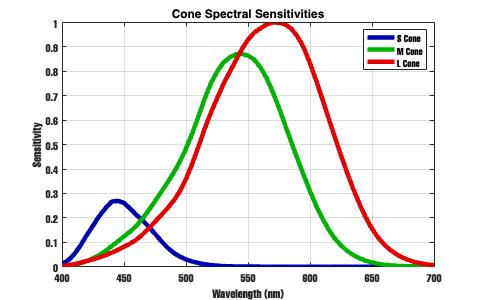

fundamentals = figure;
fundamentals.Position = [1080, 1080, 1920, 1200];

plot(WL_5, s_cone, '-', 'Color', [0,0,0.7],'LineWidth', 5);
hold on
grid on
plot(WL_5, m_cone, '-', 'Color', [0, 0.7, 0], 'LineWidth', 5);
plot(WL_5, l_cone, '-', 'Color', [0.9, 0, 0], 'LineWidth', 5);
title('Cone Spectral Sensitivities')
xlabel('Wavelength (nm)')
ylabel('Sensitivity')
ylim([0,1])
legend({'S Cone', 'M Cone', 'L Cone'}, 'Location', 'northeast')
hold off

ax=gca;
ax.FontSize = 12;
ax.FontName = 'Helvetica';

## Calculate Gain Coefficients for Environmental White

options = optimoptions('lsqnonlin','Algorithm','levenberg-marquardt', 'Display', 'off');

x0 = [1,1];

% Set environmental white
useD65 = true; useD50=false;

% Derive von Kries coefficients for cone-opponent mechanisms

if  useD65 == true
    disp('Environment = D65 white')
    gainsLLM = lsqnonlin(@(x)sum((l_cone_1.*x(1) - surround_1.*x(2)).*d65spectrum'), x0, [], [], options);
    gainsMLM = lsqnonlin(@(x)sum((m_cone_1.*x(1) - surround_1.*x(2)).*d65spectrum'), x0, [], [], options);
    gainsSLM = lsqnonlin(@(x)sum((s_cone_1.*x(1) - surround_1.*x(2)).*d65spectrum'), x0, [], [], options);
    gainsSM = lsqnonlin(@(x) sum((s_cone_1.*x(1) - m_cone_1.*x(2)).*d65spectrum'), x0, [], [], options);
    gainsSL = lsqnonlin(@(x) sum((s_cone_1.*x(1) - l_cone_1.*x(2)).*d65spectrum'), x0, [], [], options);
elseif useD50 == true
    disp('Environment = D50 white')
    gainsLLM = lsqnonlin(@(x)sum((l_cone_1.*x(1) - surround_1.*x(2)).*d50spectrum'), x0, [], [], options);
    gainsMLM = lsqnonlin(@(x)sum((m_cone_1.*x(1) - surround_1.*x(2)).*d50spectrum'), x0, [], [], options);
    gainsSLM = lsqnonlin(@(x)sum((s_cone_1.*x(1) - surround_1.*x(2)).*d50spectrum'), x0, [], [], options);
    gainsSM = lsqnonlin(@(x) sum((s_cone_1.*x(1) - m_cone_1.*x(2)).*d50spectrum'), x0, [], [], options);
    gainsSL = lsqnonlin(@(x) sum((s_cone_1.*x(1) - l_cone_1.*x(2)).*d50spectrum'), x0, [], [], options);
else
    disp('Environment = EE White')
    gainsLLM = lsqnonlin(@(x) sum(l_cone_1.*x(1) - surround_1.*x(2)), x0, [], [], options);
    gainsMLM = lsqnonlin(@(x) sum(m_cone_1.*x(1) - surround_1.*x(2)), x0, [], [], options);
    gainsSLM = lsqnonlin(@(x) sum(s_cone_1.*x(1) - surround_1.*x(2)), x0, [], [], options);
    gainsSM = lsqnonlin(@(x) sum(s_cone_1.*x(1) - m_cone_1.*x(2)), x0, [], [], options);
    gainsSL = lsqnonlin(@(x) sum(s_cone_1.*x(1) - l_cone_1.*x(2)), x0, [], [], options);
end

Environment = D65 white


## Calculate and Plot Cone and Color Opponent Mechanisms

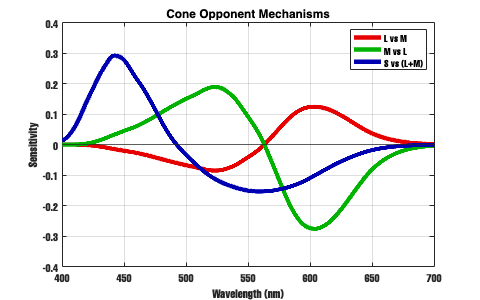

% Calculate and plot cone-opponent mechanisms

LvsM = l_cone_01.*gainsLLM(1) - surround_01.*gainsLLM(2);
MvsL = m_cone_01.*gainsMLM(1) - surround_01.*gainsMLM(2);
SvsLM = s_cone_01.*gainsSLM(1) - surround_01.*gainsSLM(2);
SvsM = s_cone_01.*gainsSM(1) - m_cone_01.*gainsSM(2);
SvsL = s_cone_01.*gainsSL(1) - l_cone_01.*gainsSL(2);

coneopp = figure;
coneopp.Position = [1080, 1080, 1920, 1200];

plot(WL_01, LvsM, '-', 'Color', [0.9,0,0], 'LineWidth', 5);
hold on
grid on
plot(WL_01, MvsL, '-', 'Color', [0,0.7,0], 'LineWidth', 5);
plot(WL_01, SvsLM, '-', 'Color', [0,0,0.7], 'LineWidth', 5);
yline(0)
ylim([-0.4, 0.4]);
title('Cone Opponent Mechanisms')
xlabel('Wavelength (nm)')
ylabel('Sensitivity')
legend({'L vs M', 'M vs L', 'S vs (L+M)'}, 'Location', 'northeast')
hold off

ax = gca;
ax.FontSize = 12;
ax.FontName = 'Helvetica';

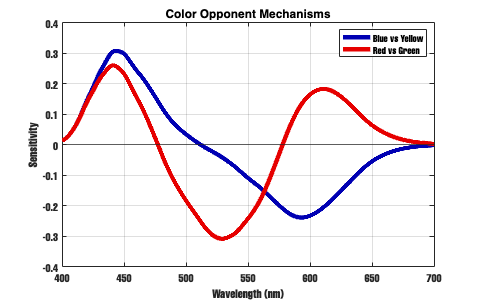


% Calculate and plot color-opponent mechanisms

BY = SvsLM - LvsM;
RG = SvsLM - MvsL;

coloropp = figure;
coloropp.Position = [1080, 1080, 1920, 1200];

plot(WL_01, BY, '-', 'Color', [0,0,0.7], 'LineWidth', 5);
hold on
grid on
plot(WL_01, RG, '-', 'Color', [0.9,0,0], 'LineWidth', 5);
yline(0)
ylim([-0.4, 0.4])
title('Color Opponent Mechanisms')
xlabel('Wavelength (nm)')
ylabel('Sensitivity')
legend({'Blue vs Yellow', 'Red vs Green'}, "Location", 'northeast')
hold off

ax = gca;
ax.FontSize = 12;
ax.FontName = 'Helvetica';

## Calculate Unique Hues

% Unique Green - crossing of BY system

uniqueGreen_idx = find([0 diff(sign(BY))]~=0);
uniqueGreen = WL_01(uniqueGreen_idx);

% Unique Blue and Unique Yellow - crossings of RG system

uniqueBY_idx = find([0 diff(sign(RG))]~=0);
uniqueBlue = WL_01(uniqueBY_idx(1));
uniqueYellow = WL_01(uniqueBY_idx(2));

% Deutan crossing - crossing of S vs L system

deutanGreen_idx = find([0 diff(sign(SvsL))]~=0);
deutanGreen = WL_01(deutanGreen_idx);

% Protan crossing - crossing of S vs M system

protanGreen_idx = find([0 diff(sign(SvsM))]~=0);
protanGreen = WL_01(protanGreen_idx);

% Unique Red on line of purples - balance of 400 and 700 nm light responses

rNull = lsqnonlin(@(x) BY(WL_01==430).*x(1)-abs(BY(WL_01==670)).*x(2), x0, [1,1], [], options);
rXYZ = JuddTristimulus_01(WL_01==430,:)*rNull(1)+JuddTristimulus_01(WL_01==670,:)*rNull(2);
r_xy = rXYZ./sum(rXYZ);

% Display calculated values for the spectral unique hues and dichromat
% neutral points

disp(['Unique Blue is ', num2str(uniqueBlue), ' nm']);

Unique Blue is 477.2 nm


disp(['Unique Green is ', num2str(uniqueGreen), ' nm']);

Unique Green is 511.6 nm


disp(['Unique Yellow is ', num2str(uniqueYellow), ' nm']);

Unique Yellow is 577.9 nm


disp(['The Protan neutral point is ', num2str(protanGreen), ' nm'])

The Protan neutral point is 488.1 nm


disp(['The Deutan neutral point is ', num2str(deutanGreen), ' nm'])

The Deutan neutral point is 494.5 nm


## Set Weber Fractions and Establish LMS Ratios for Adaptation

kLM = 0.12;
kS = 0.17;

LMSRatios = [(l_cone_01'-m_cone_01')./m_cone_01', zeros(length(l_cone_01),1), (s_cone_01'-m_cone_01')./m_cone_01'];


## Plot RG and BY Null Points on CIE xy Chromaticity Diagram

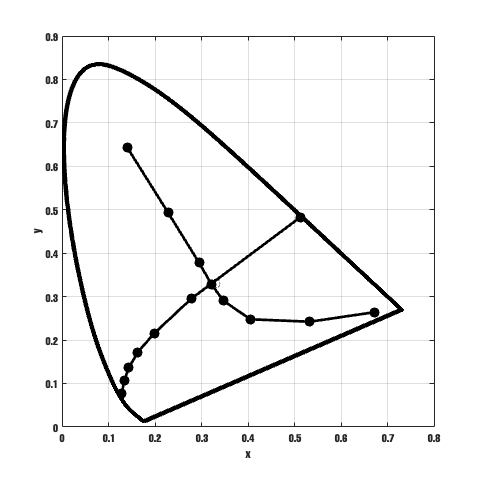

% Plot Judd xy Chromaticity Space

xyPlot = figure;
xyPlot.Position = [1080, 1080, 1080, 1080];

plot(Judd_xy(:,1), Judd_xy(:,2), '-k', 'LineWidth', 5);
grid on
hold on
plot([Judd_xy(1,1), Judd_xy(end,1)], [Judd_xy(1,2), Judd_xy(end,2)], '-k', 'LineWidth', 5);
plot(0.33, 0.33, 'Marker', 'o', 'MarkerFaceColor', 'w', 'MarkerEdgeColor', 'k', 'MarkerSize', 10);
ylim([0,0.9])
xlim([0,0.8])
xlabel('x')
ylabel('y')

% Calculate and Plot Unique Red and Unique Green Hues

shortWavelength = 480;
longWavelengths = [530, 550, 570, 580, 590, 610, 640, 655];
rg_values = zeros(length(longWavelengths),2);

for i = 1:length(longWavelengths)
    null = lsqnonlin(@(x) abs(BY(WL_01==shortWavelength)).*x(1)-abs(BY(WL_01==longWavelengths(i))).*x(2), x0, [], [1,1], options);
    null = null./sum(null);
    
    L_adp = (LMSRatios(WL_01==longWavelengths(i),1)*null(2)+LMSRatios(WL_01==shortWavelength,1)*null(1))*kLM;
    S_adp = (LMSRatios(WL_01==shortWavelength,3)*null(1)+LMSRatios(WL_01==longWavelengths(i),3)*null(2))*kS;
    
    L_adapted = l_cone_01-(l_cone_01.*L_adp);
    M_adapted = m_cone_01;
    S_adapted = s_cone_01-(s_cone_01.*S_adp);
    surround_adapted = L_adapted.*percent_L+M_adapted.*percent_M;
    LvsM_adapted = L_adapted.*gainsLLM(1) - surround_adapted.*gainsLLM(2);
    MvsL_adapted = M_adapted.*gainsMLM(1) - surround_adapted.*gainsMLM(2);
    SvsLM_adapted = S_adapted.*gainsSLM(1) - surround_adapted.*gainsSLM(2);
    BY_adapted = SvsLM_adapted - LvsM_adapted;

    nullPoint = lsqnonlin(@(x) abs(BY_adapted(WL_01==shortWavelength)).*x(1)-abs(BY_adapted(WL_01==longWavelengths(i))).*x(2), x0, [1,1], [], options);

    point_XYZ = JuddTristimulus_01(WL_01==shortWavelength,:).*nullPoint(1)+JuddTristimulus_01(WL_01==longWavelengths(i),:).*nullPoint(2);
    point_xy = [point_XYZ(1)./sum(point_XYZ), point_XYZ(2)./sum(point_XYZ)];
    rg_values(i,:) = [point_xy(1), point_xy(2)];
end

plot(rg_values(:,1), rg_values(:,2), '-k', 'LineWidth', 3, 'Marker', 'o', 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k', 'MarkerSize', 8)

% Calculate and Plot Unique Blue and Unique Yellow Hues

bluefraction = [0.99, 0.965, 0.94, 0.9, 0.835, 0.675, 0.01];
SW = round(linspace(440, uniqueBlue, length(bluefraction)),0);
by_values = zeros(length(bluefraction),2);

for i = 1:length(bluefraction)
    L_a = ((LMSRatios(WL_01==SW(i),1)*bluefraction(i))+(LMSRatios(WL_01==571,1)*(1-bluefraction(i))))*kLM;
    S_a = ((LMSRatios(WL_01==SW(i),3)*bluefraction(i))+(LMSRatios(WL_01==571,3)*(1-bluefraction(i))))*kS;

    L_adapted = l_cone_01-(l_cone_01.*L_a);
    M_adapted = m_cone_01;
    S_adapted = s_cone_01-(s_cone_01.*S_a);
    surround_adapted = L_adapted.*percent_L+M_adapted.*percent_M;
    
    LvsM_adapted = L_adapted.*gainsLLM(1) - surround_adapted.*gainsLLM(2);
    MvsL_adapted = M_adapted.*gainsMLM(1) - surround_adapted.*gainsMLM(2);
    SvsLM_adapted = S_adapted.*gainsSLM(1) - surround_adapted.*gainsSLM(2);
    BY_adapted = SvsLM_adapted - LvsM_adapted;
    RG_adapted = SvsLM_adapted - MvsL_adapted;

    uniqueBY_idx = find([0 diff(sign(RG_adapted))]~=0);
    uniqueBlue_adapted = WL_01(uniqueBY_idx(1));
    uniqueYellow_adapted = WL_01(uniqueBY_idx(2));

    point_XYZ = JuddTristimulus_01(WL_01==uniqueBlue_adapted,:).*bluefraction(i)+JuddTristimulus_01(WL_01==uniqueYellow_adapted,:).*(1-bluefraction(i));
    point_xy = point_XYZ./sum(point_XYZ);
    by_values(i,:) = [point_xy(1), point_xy(2)];
   
end

plot(by_values(:,1), by_values(:,2), '-k', 'LineWidth', 3, 'Marker', 'o', 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k', 'MarkerSize', 8);

hold off

ax = gca;
ax.FontSize = 12;
ax.FontName = 'Helvetica';

## Plot RG and BY Null Points in CIE u'v' Chromaticity Diagram 

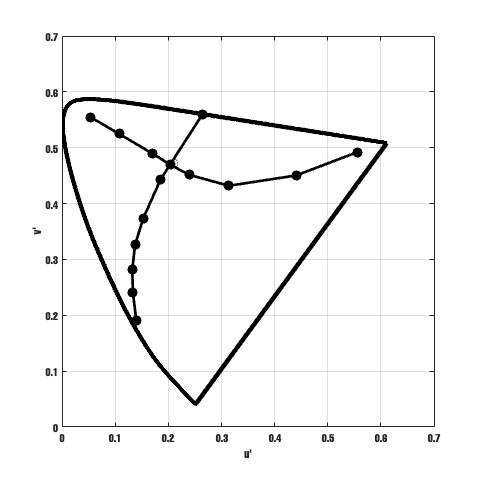

% EE White in u'v' space
wt_uv = xytouv([0.33, 0.33]);

% RG Values in u'v' space

rg_uv = zeros(size(rg_values));

for i = 1:length(rg_values)
    rg_uv(i,:) = xytouv(rg_values(i,:));
end

% BY Values in 'u'v' space

by_uv = zeros(size(by_values));

for i = 1:length(by_values)
    by_uv(i,:) = xytouv(by_values(i,:));
end

% Plot unique hue loci in u'v' chromaticity space

uvPlot = figure;
uvPlot.Position = [1080, 1080, 1155, 1155];

plot(Judd_uv(:,1), Judd_uv(:,2), '-k', 'LineWidth', 5);
grid on
hold on
xlabel("u'")
ylabel("v'")
plot(wt_uv(1), wt_uv(2), 'Marker', 'o', 'MarkerFaceColor', 'w', 'MarkerEdgeColor', 'k', 'MarkerSize', 10);
ylim([0,0.7])
xlim([0,0.7])
plot([Judd_uv(1,1), Judd_uv(end,1)], [Judd_uv(1,2), Judd_uv(end,2)], '-k', 'LineWidth', 5);
plot(by_uv(:,1), by_uv(:,2), '-k', 'LineWidth', 3, 'Marker', 'o', 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k', 'MarkerSize', 8);
plot(rg_uv(:,1), rg_uv(:,2), '-k', 'LineWidth', 3, 'Marker', 'o', 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k', 'MarkerSize', 8);
hold off

ax = gca;
ax.FontSize = 12;
ax.FontName = 'Helvetica';